# Inverse Filtering Analysis

#### Load the images I1 and I2

load("img_restoration.mat");

#### Visualize Images

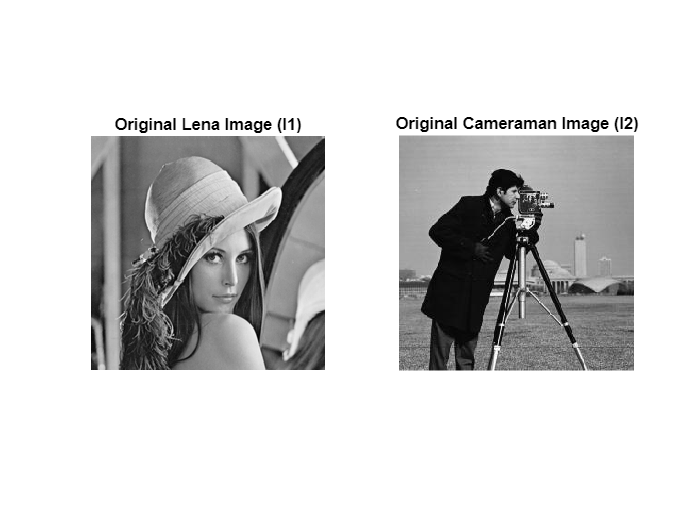

figure;
subplot(1, 2, 1); imshow(I1, []); title("Original Lena Image (I1)");
subplot(1, 2, 2); imshow(I2, []); title("Original Cameraman Image (I2)");

#### Choose one of the Images

original_image = I1; %choose between I1 and I2

#### Apply Linear Motion Deformation

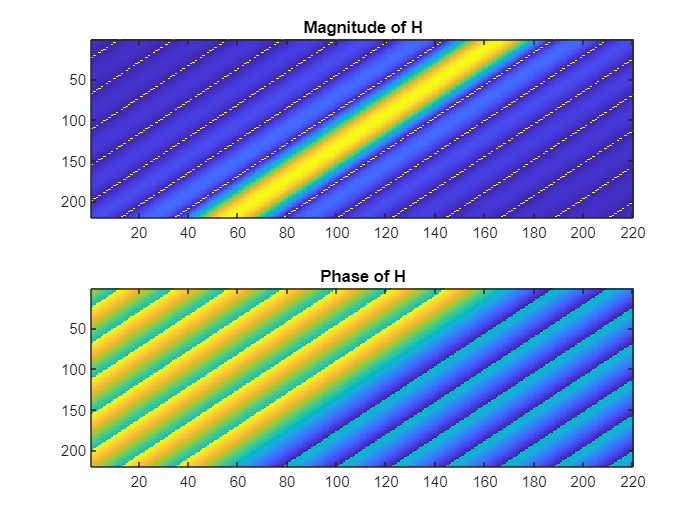

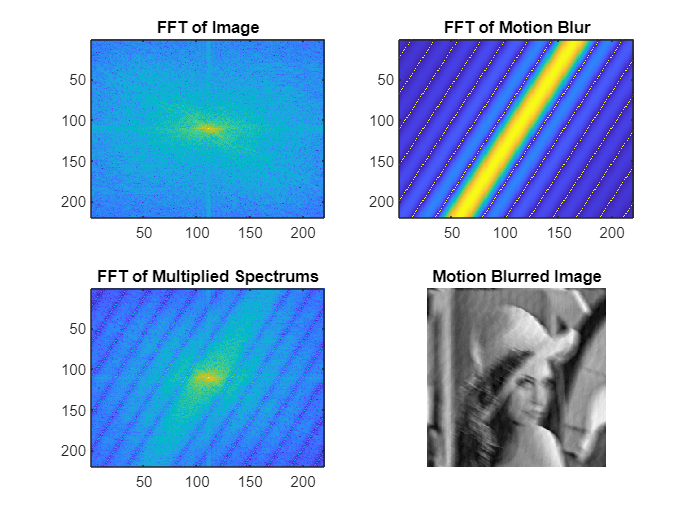

a = 10; % Horizontal motion coefficient
b = 5; % Vertical motion coefficient
T = 1; % Exposure time
[motion_blurred_image,  motion_blur_kernel_spectrum] = applyLinearMotionBlur(a, b, T, original_image, true);

#### Add Gaussian noise

mean = 0;
variance = 10;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;

#### Visualize Motion Blurred Noisy Image

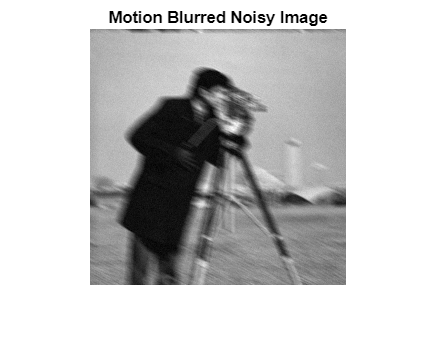

figure; imshow(noisy_motion_blurred_image, []); title("Motion Blurred Noisy Image");

#### Apply Inverse filtering to the image with different noise values

var_vec = 0:0.01:100;
var_vec = exp(var_vec);

snr_db_values = zeros(size(var_vec));
mse_values = zeros(size(var_vec));
max_snr = -inf;
min_mse = 0;
best_var_vec = 0;
for i = 1:length(var_vec)
    restored_image = inverseFilter(motion_blurred_image, motion_blur_kernel_spectrum, var_vec(i), false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_var_vec = var_vec(i);
    end
end

#### Plot the SNR (dB) values and MSE values corresponding to different variance values

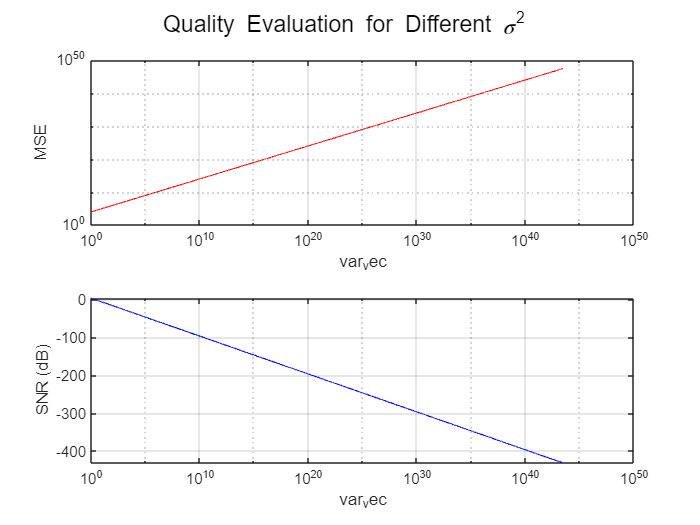

figure;
subplot(2, 1, 1); loglog(var_vec, mse_values, "Color", "red"); xlabel("var_vec"); ylabel("MSE"); grid on;
subplot(2, 1, 2); semilogx(var_vec, snr_db_values, "Color", "blue"); xlabel("var_vec"); ylabel("SNR (dB)"); grid on;
sgtitle("Quality Evaluation for Different \sigma^2 ");

#### Visualize the results of best choice of variance 

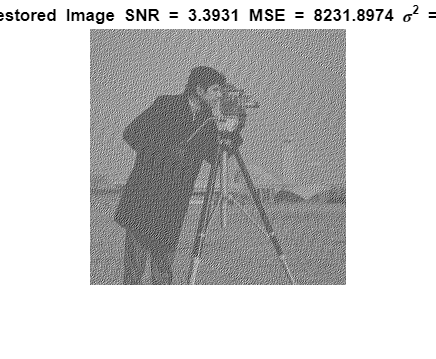

figure;
title_text = "Best Restored Image SNR = " + max_snr ...
    + " MSE = " + min_mse + " \sigma^2 = " + best_var_vec;
imshow(best_restored_image, []); title(title_text);

#### Now compute the inverse filtered image for only a motion blurred image

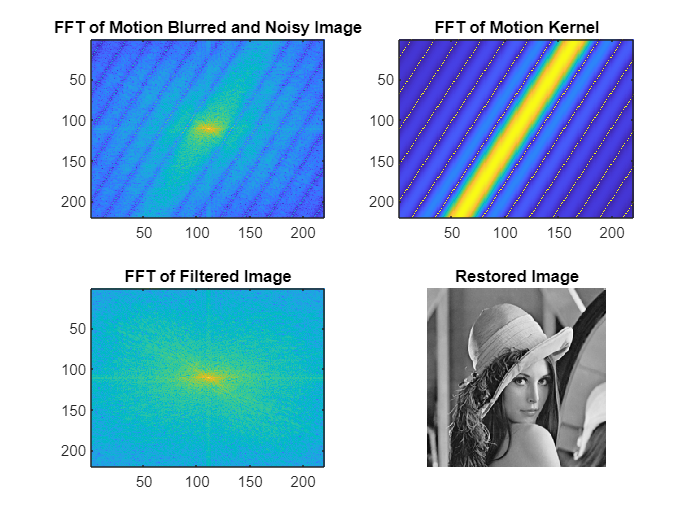

restored_image = inverseFilter(motion_blurred_image, motion_blur_kernel_spectrum, 0, true);

snr_db_values_motion = computeSNR_db(original_image, restored_image);
mse_values_motion = computeMSE(original_image, restored_image);

# Geometric Mean Filtering Analysis

### Applying the geometric mean filter with only motion blur

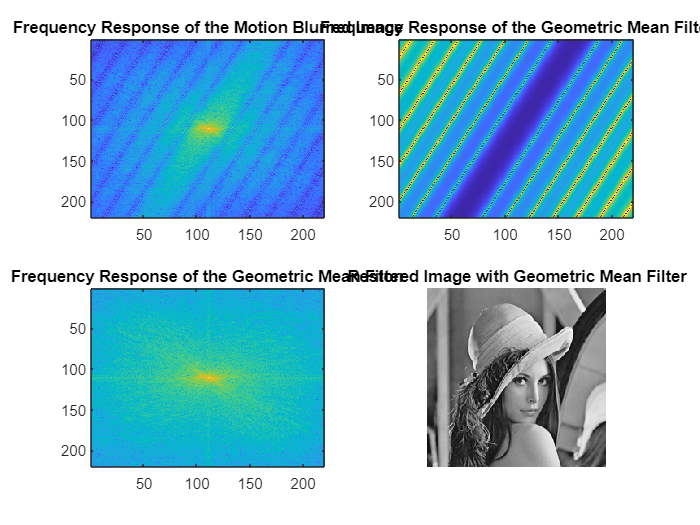

alpha = 0.5;
beta = 1;
restored_image_gm = GeometricMeanFilter(motion_blurred_image, motion_blur_kernel_spectrum, alpha,beta,0, true);

snr_db_values_motion_gm = computeSNR_db(original_image, restored_image);
mse_values_motion_gm = computeMSE(original_image, restored_image);

#### Using Different K values Apply Geometric Mean Filter to the Noisy Image

mean = 0;
variance = 10;
noise = mean + sqrt(variance) * randn(size(motion_blurred_image));
noisy_motion_blurred_image = motion_blurred_image + noise;
k = -10:0.01:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
max_snr = 0;
min_mse = 0;
best_k = 0;
alpha = 0.5;
beta = 1;
for i = 1:length(k)
    restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alpha,beta, k(i), false);
    snr_db_values(i) = computeSNR_db(original_image, restored_image);
    mse_values(i) = computeMSE(original_image, restored_image);
    if (snr_db_values(i) > max_snr)
        best_restored_image = restored_image;
        min_mse = mse_values(i);
        max_snr = snr_db_values(i);
        best_k = k(i);
    end
end

#### Plot the SNR (dB) values and MSE values corresponding to different K values

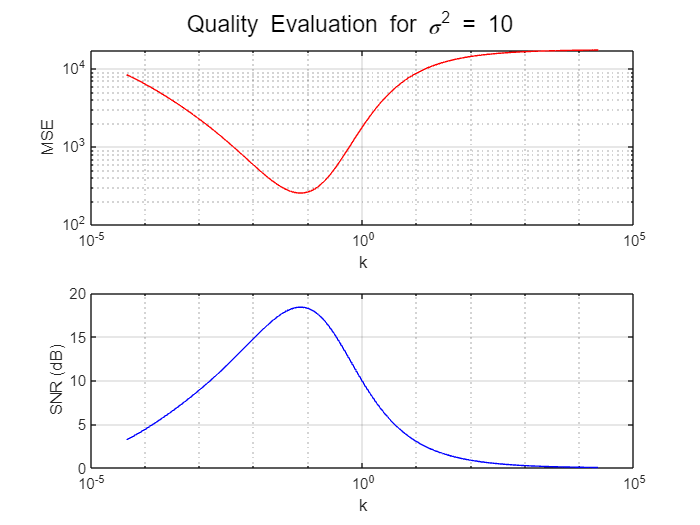

figure;
subplot(2, 1, 1); loglog(k, mse_values, "Color", "red"); xlabel("k"); ylabel("MSE"); grid on;
subplot(2, 1, 2); semilogx(k, snr_db_values, "Color", "blue"); xlabel("k"); ylabel("SNR (dB)"); grid on;
sgtitle("Quality Evaluation for \sigma^2 = " + variance);

#### Visualize the results of best K for a certain noise power

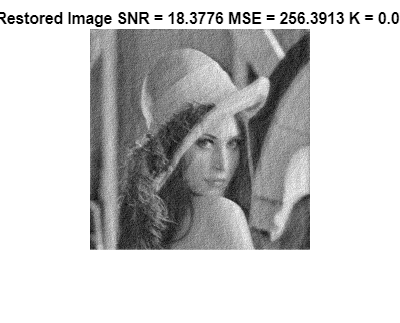

figure;
title_text = "Best Restored Image SNR = " + max_snr ...
    + " MSE = " + min_mse + " K = " + best_k;
imshow(best_restored_image, []); title(title_text);

#### Loop through various noise powers and find best K for each

varience_vec = 0:5:100;
best_k_vec = zeros(size(varience_vec));
max_snr_vec = zeros(size(varience_vec));
min_mse_vec = zeros(size(varience_vec));
alpha = 0.3;
beta =1;
k = -10:0.01:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
max_snr = 0;
min_mse = 0;
best_k = 0;
for j = 1:length(varience_vec)
    varience = varience_vec(j);
    mean = 0;
    noise = mean + sqrt(varience) * randn(size(motion_blurred_image));
    noisy_motion_blurred_image = motion_blurred_image + noise;
    for i = 1:length(k)
        restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alpha,beta, k(i), false);
        snr_db_values(i) = computeSNR_db(original_image, restored_image);
        mse_values(i) = computeMSE(original_image, restored_image);
        if (snr_db_values(i) > max_snr)
            best_restored_image = restored_image;
            min_mse = mse_values(i);
            max_snr = snr_db_values(i);
            best_k = k(i);
        end
    end
    min_mse_vec(j) = min_mse;
    max_snr_vec(j) = max_snr;
    best_k_vec(j) = best_k;
    %disp(j)
end

#### Plot the metrics

figure;
subplot(2, 1, 1); semilogy(varience_vec, min_mse_vec, "Color", "red"); xlabel("\sigma^2"); ylabel("MSE"); grid on;
subplot(2, 1, 2); plot(varience_vec, max_snr_vec, "Color", "blue"); xlabel("\sigma^2"); ylabel("SNR (dB)"); grid on;
sgtitle("Evaluation of Geometric Mean Filter for Various Noise Powers");

## Loop through various alpha values and find the best K for each

varience_vec = 0:5:100;
alpha = -1:0.1:1;
best_k_a = zeros(length(alpha), length(varience_vec));
max_snr_a = zeros(length(alpha), length(varience_vec));
min_mse_a = zeros(length(alpha), length(varience_vec));
beta =1;
k = -10:0.1:10;
k = exp(k);
snr_db_values = zeros(size(k));
mse_values = zeros(size(k));
    for l = 1:length(varience_vec)
    varience = varience_vec(l);
    mean = 0;
    noise = mean + sqrt(varience) * randn(size(motion_blurred_image));
    noisy_motion_blurred_image = motion_blurred_image + noise;

    for j = 1:length(alpha)
    alfa = alpha(j);
            max_snr = 0;
    min_mse = 0;
    best_k = 0;
    for i = 1:length(k)
        restored_image = GeometricMeanFilter(noisy_motion_blurred_image, motion_blur_kernel_spectrum,alfa,beta, k(i), false);
        snr_db_values(i) = computeSNR_db(original_image, restored_image);
        mse_values(i) = computeMSE(original_image, restored_image);
        if (snr_db_values(i) > max_snr)
            best_restored_image = restored_image;
            min_mse = mse_values(i);
            max_snr = snr_db_values(i);
            best_k = k(i);
        end
    end
        max_snr_a(j, l) = max_snr;
        min_mse_a(j, l) = min_mse;
        best_k_a(j, l) = best_k;
    end

    disp(['Completed Variance iteration: ', num2str(l)]);
    end

Completed Variance iteration: 1
Completed Variance iteration: 2
Completed Variance iteration: 3
Completed Variance iteration: 4
Completed Variance iteration: 5
Completed Variance iteration: 6
Completed Variance iteration: 7
Completed Variance iteration: 8
Completed Variance iteration: 9
Completed Variance iteration: 10


Plot the metrics

figure;
[X, Y] = meshgrid(varience_vec, alpha);
surf(X, Y, max_snr_a);
xlabel('Variance');
ylabel('Alpha');
zlabel('Max SNR');
title('Max SNR vs Alpha and Variance');
colorbar;

% Plotting min_mse_a
figure;
surf(X, Y, min_mse_a);
xlabel('Variance');
ylabel('Alpha');
zlabel('Min MSE');
title('Min MSE vs Alpha and Variance');
colorbar;
% Choose a specific variance value for plotting
fixed_variance_index = 5; % Index representing a particular variance, e.g., variance_vec(25)

% Plotting max_snr_a against alpha for the chosen variance
figure;
plot(alpha, max_snr_a(:, fixed_variance_index), '-o');
xlabel('Alpha');
ylabel('Max SNR');
title(['Max SNR vs Alpha for Variance = ', num2str(varience_vec(fixed_variance_index))]);
grid on;

% Plotting min_mse_a against alpha for the chosen variance
figure;
plot(alpha, min_mse_a(:, fixed_variance_index), '-o');
xlabel('Alpha');
ylabel('Min MSE');
title(['Min MSE vs Alpha for Variance = ', num2str(varience_vec(fixed_variance_index))]);
grid on;
% Choose a specific alpha value for plotting
fixed_alpha_index = 10; % Index representing a particular alpha, e.g., alpha(30)

% Plotting max_snr_a against variance for the chosen alpha
figure;
plot(varience_vec, max_snr_a(fixed_alpha_index, :), '-o');
xlabel('Variance');
ylabel('Max SNR');
title(['Max SNR vs Variance for Alpha = ', num2str(alpha(fixed_alpha_index))]);
grid on;

% Plotting min_mse_a against variance for the chosen alpha
figure;
plot(varience_vec, min_mse_a(fixed_alpha_index, :), '-o');
xlabel('Variance');
ylabel('Min MSE');
title(['Min MSE vs Variance for Alpha = ', num2str(alpha(fixed_alpha_index))]);
grid on;
figure;
imshow(best_restored_image, []);